# Arrayed Waveguide Grating Simulation Model

clear; clc;
addpath(genpath('./'));

% Show intermediate response plots? 
plot_intermediate = true;

Explicit simulation of the AWG using a scalar field description. The following are the model parameters:

AWG = struct();

AWG.clad = @SiO2;       % top cladding material
AWG.core = @Si;         % core (guiding) material
AWG.subs = @SiO2;       % sub cladding material

% Design parameters

AWG.lambda_c = 1.550;   % design center wavelength

AWG.w = 0.450;          % array waveguide core width
AWG.h = 0.220;          % waveguide core height

AWG.N = 9;              % number of outputs
AWG.M = 40;             % number of arrayed waveguides
AWG.m = 35;             % diffraction order
AWG.R = 100;            % focal length
AWG.d = 1.8;            % aperture spacing
AWG.do = 1.2;           % output waveguide spacing
AWG.wi = 1.0;           % input aperture width
AWG.wg = AWG.d - 0.2;   % array aperture width
AWG.wo = 1.0;           % output aperture width

Show device intermediate response for two wavelengths

awg_simulate(AWG, AWG.lambda_c + 1e-3, 'plot', plot_intermediate);
awg_simulate(AWG, AWG.lambda_c, 'plot', plot_intermediate);

Show full spectrum response

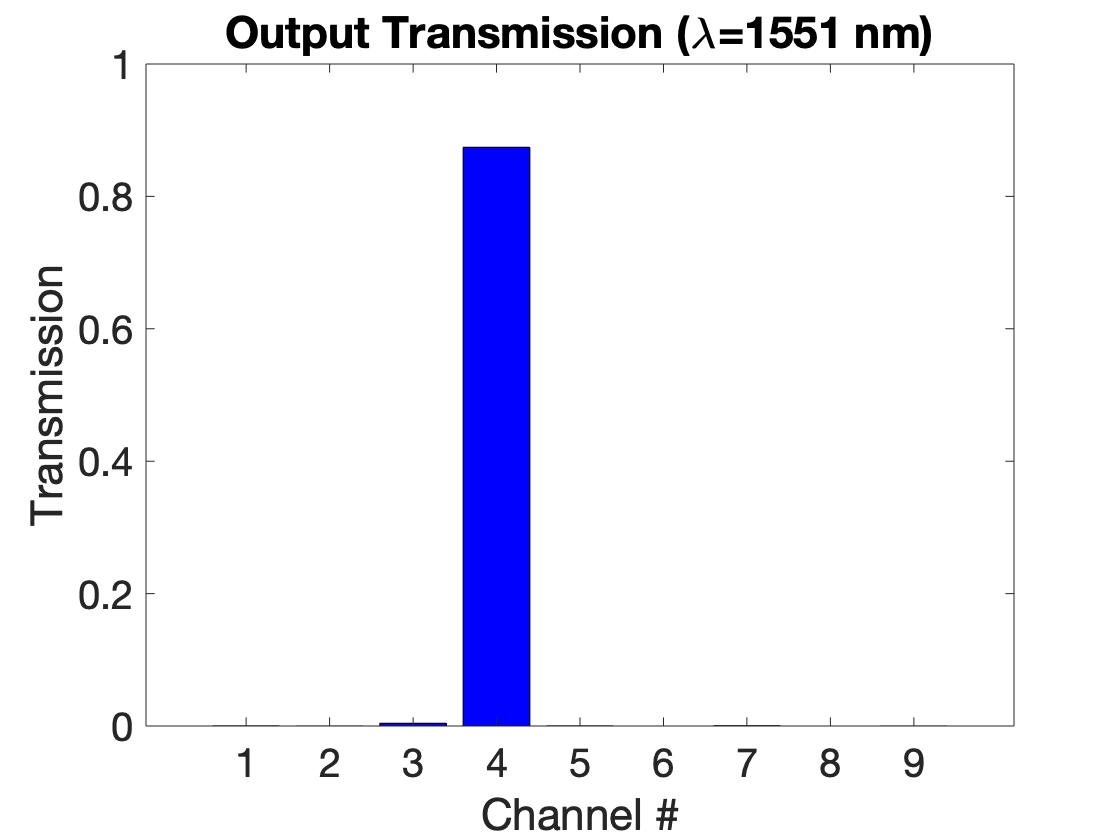

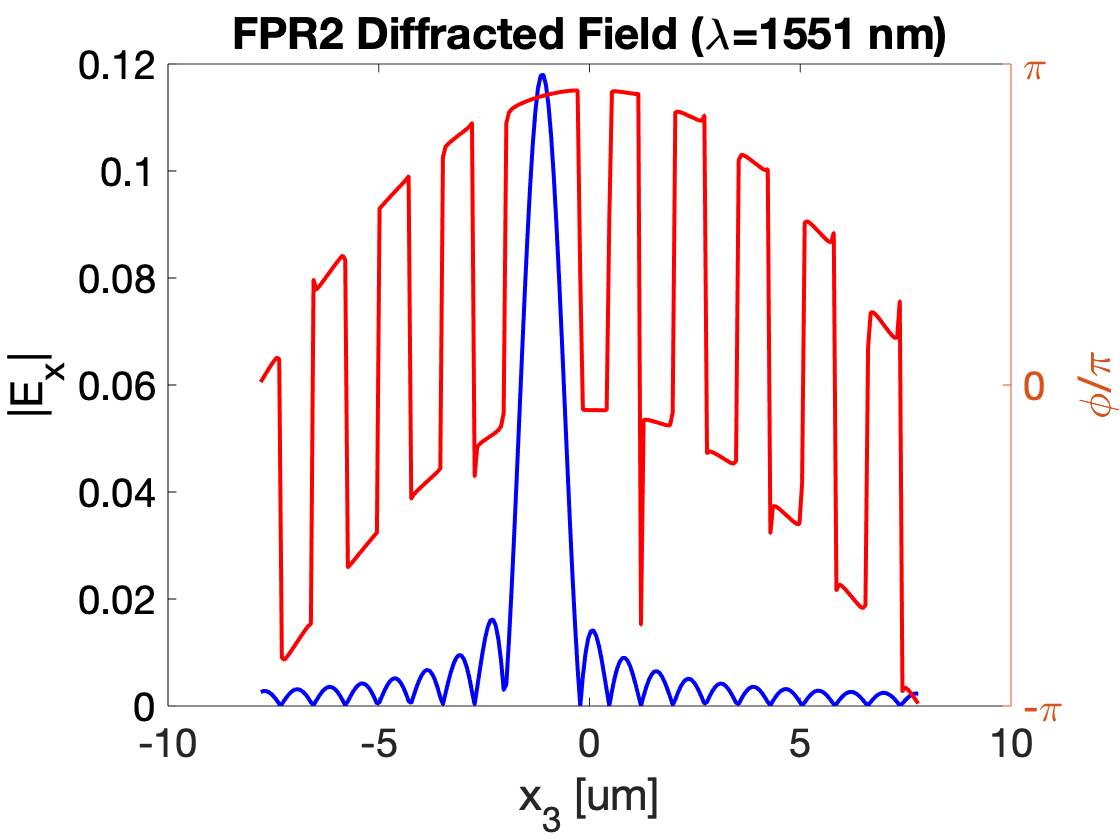

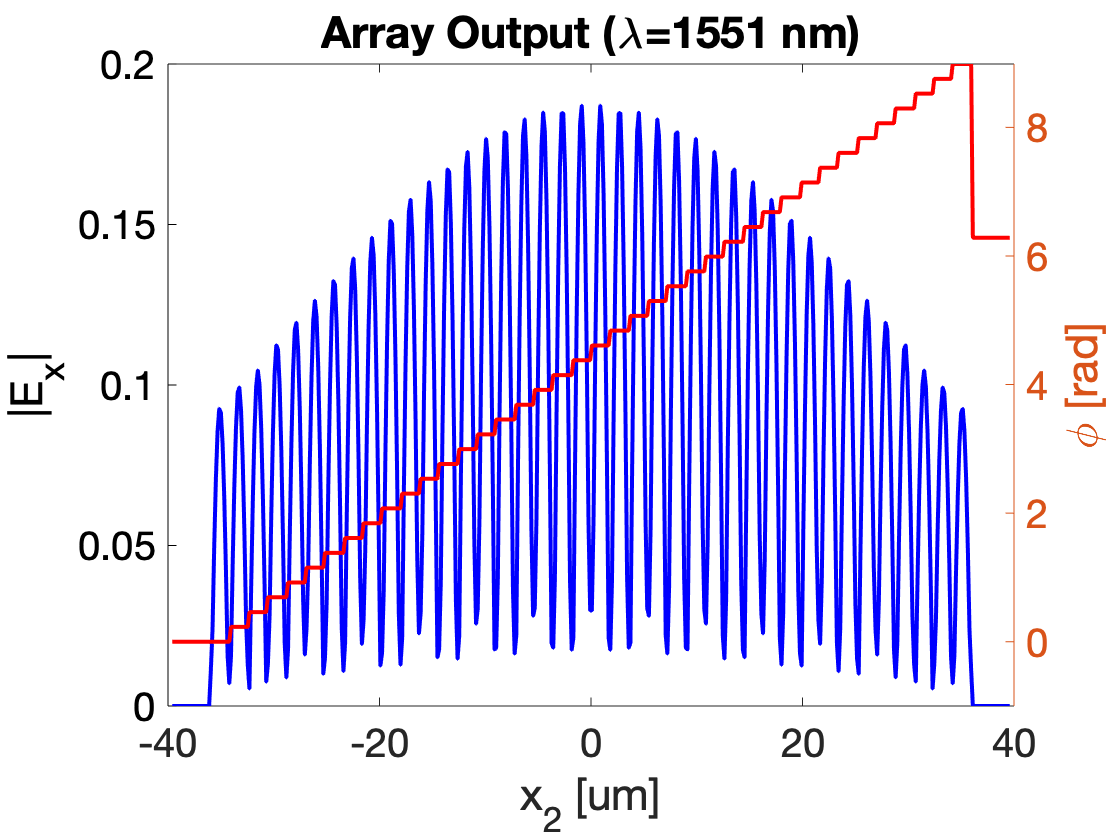

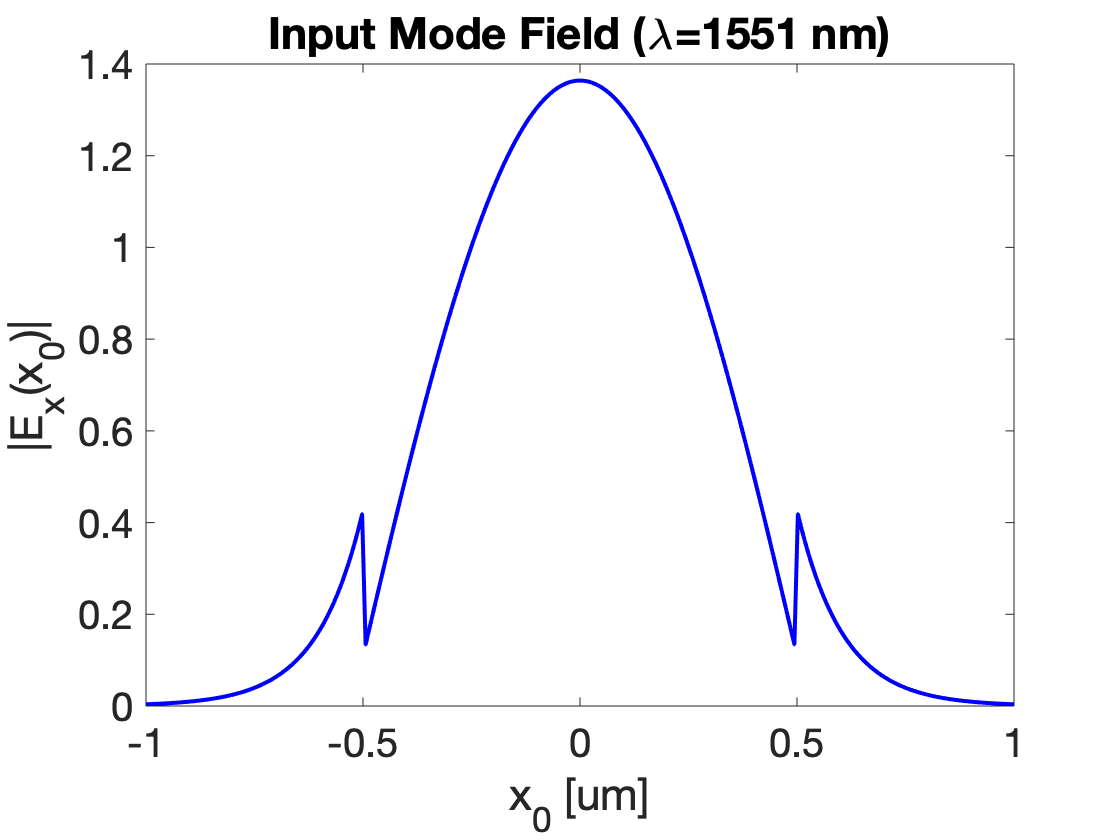

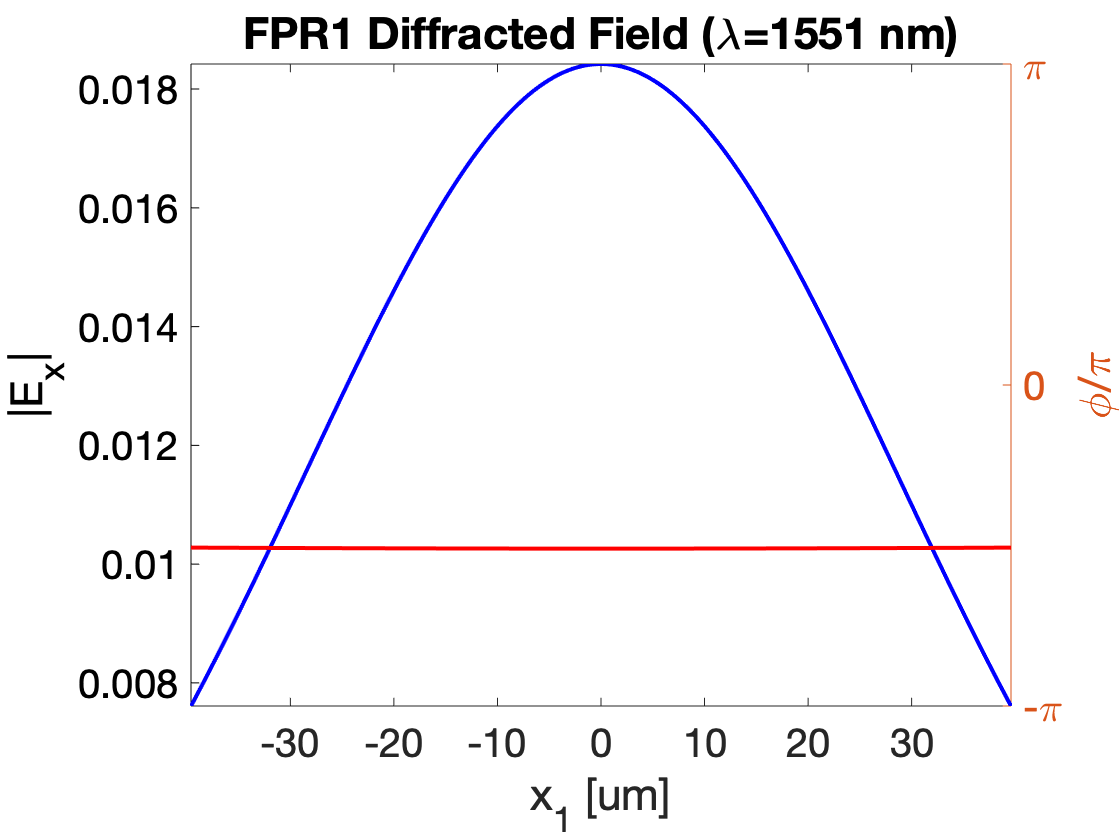

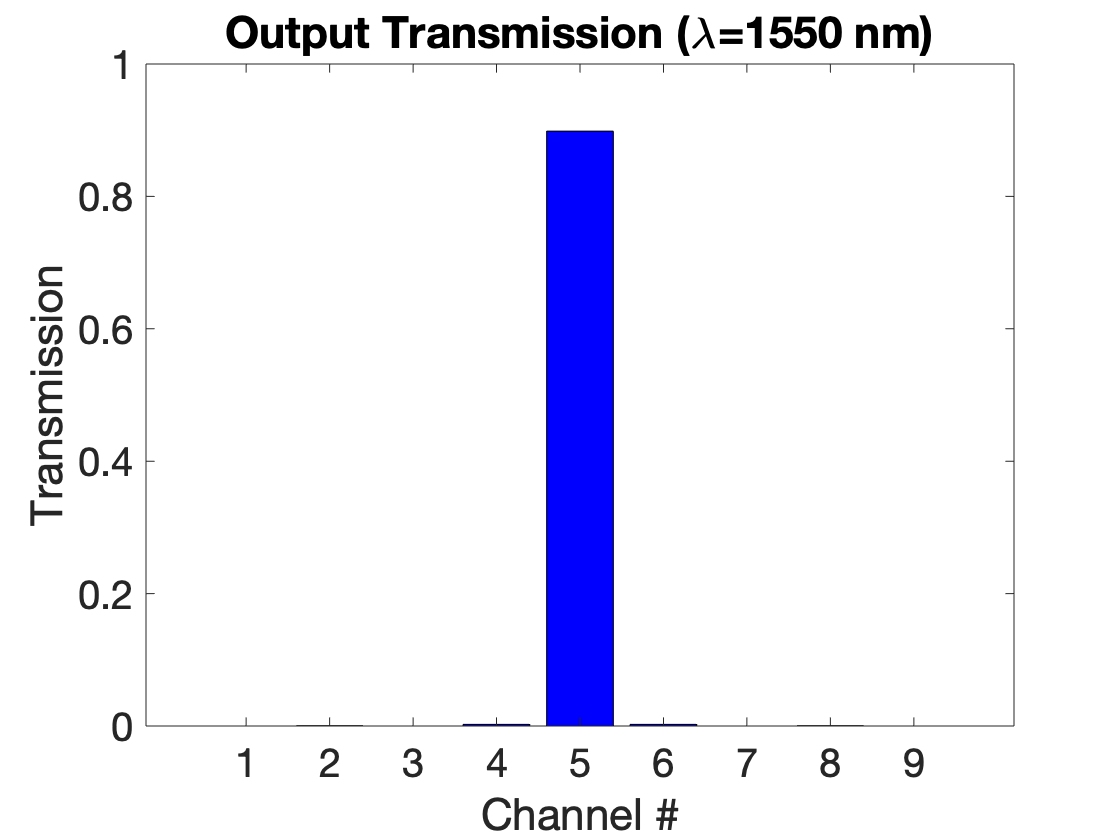

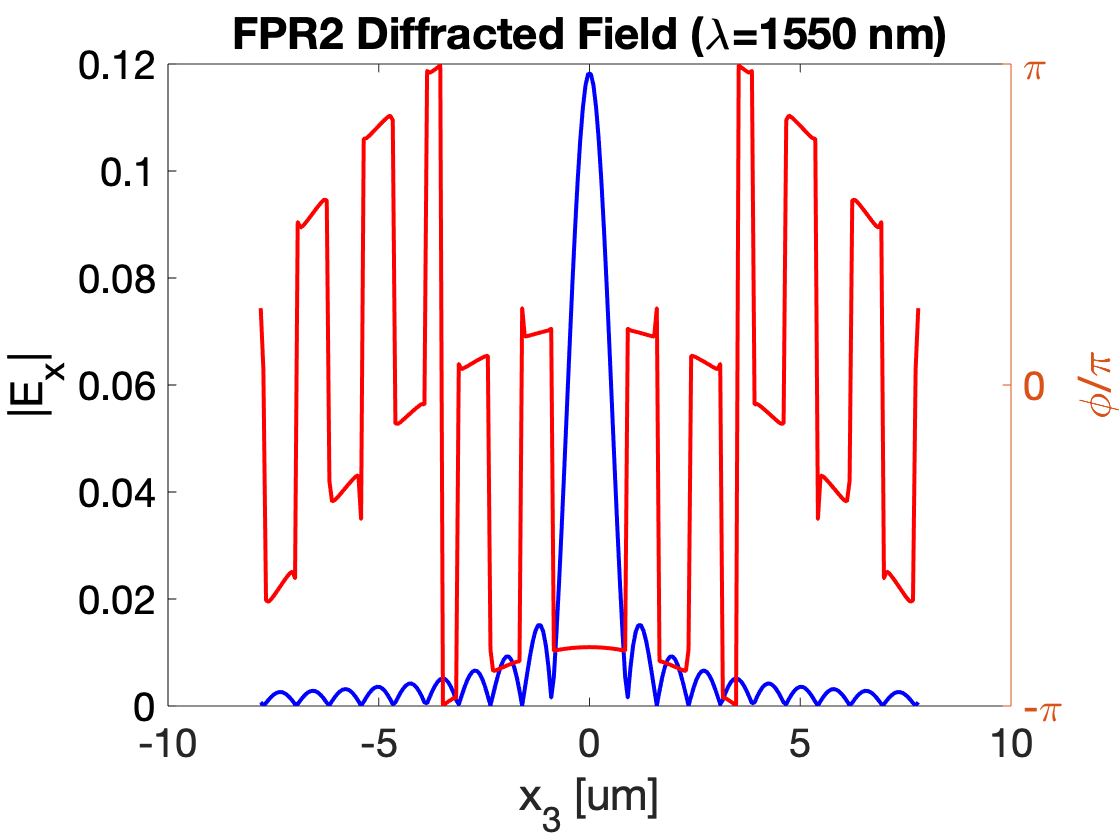

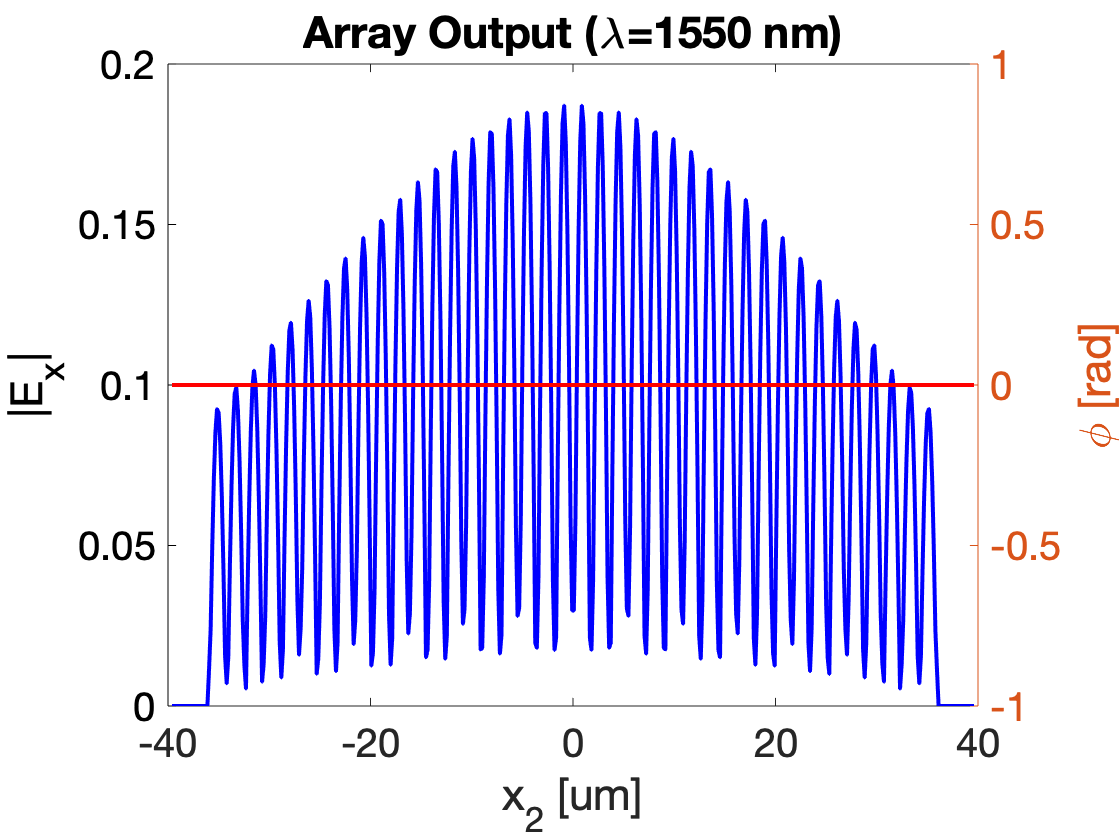

[T, lambda] = awg_spectrum(AWG, AWG.lambda_c, 0.012, 'plot', true, 'samples', 100);

Analyse spectrum and extract measurements

disp(awg_analyse(lambda, T))

                                 Value  
                                ________

    Insertion loss [dB]          0.54119
    Loss non-uniformity [dB]    0.029098
    Channel spacing [nm]         0.60606
    3dB bandwidth [nm]            0.9697
    10dB bandwidth [nm]           1.4545
    Crosstalk level [dB]         -6.9653

